clear; clc; close all;
load Gridless_Network
addpath('D:\D\Alp\Master ODTÜ\Thesis\DOA\Codes\Direction-of-Arrival');
DOA = FunctionsOfDOA();

sensor_locations = [0 1 4 7 9]; % MRA with 5 sensors
M = length(sensor_locations);
N = sensor_locations(M) + 1;
K = 2;          % # of sources
L = 100;        % # of snapshots

phi_min = 30;
phi_max = 150;
delta_phi = 3;

SNR_dB_vals = 0:2:30;
EPOCHS = 500;

noOfMethods = 5;
RMSE = zeros(noOfMethods, length(SNR_dB_vals));

angles = phi_min:0.01:phi_max;

for epoch = 1:EPOCHS
    while true
        doa = phi_min + rand(1, 2) * (phi_max - phi_min);
        if abs(doa(2) - doa(1)) > delta_phi
            break
        end
    end
    doa = sort(doa);

    s = DOA.Source_Generate(K, L);
    A = DOA.Array_Manifold(0.5, sensor_locations, doa);
    % C = DOA.Mutual_Coupling(100, 0.1, M, sensor_locations);
    for idx = 1:length(SNR_dB_vals)
        SNR_dB = SNR_dB_vals(idx);
        n = DOA.Noise_Generate(SNR_dB, M, L);
        % y = C * A * s + n;
        y = A * s + n;

        % CBF
        spec = CBF(angles, sensor_locations, y);
        doa_est = DOA_Estimator(spec, angles, doa);
        doa_est = sort(doa_est);
        RMSE(1, idx) = RMSE(1, idx) + rmse(doa_est, doa);

        Ry = (1 / L) * (y * y');

        % Capon
        spec = Capon(angles, sensor_locations, y, Ry);
        doa_est = DOA_Estimator(spec, angles, doa);
        doa_est = sort(doa_est);
        RMSE(2, idx) = RMSE(2, idx) + rmse(doa_est, doa);

        % MUSIC
        spec = MUSIC(angles, sensor_locations, Ry, M, K);
        doa_est = DOA_Estimator(spec, angles, doa);
        doa_est = sort(doa_est);
        RMSE(3, idx) = RMSE(3, idx) + rmse(doa_est, doa);

        % DML
        spec = abs(DML(angles, sensor_locations, Ry, M));
        doa_est = DOA_Estimator(spec, angles, doa);
        doa_est = sort(doa_est);
        RMSE(4, idx) = RMSE(4, idx) + rmse(doa_est, doa);

        % Gridless DNN
        doa_est = Gridless_DNN(DOA, net, doa, sensor_locations, Ry, [phi_min delta_phi]);
        RMSE(5, idx) = RMSE(5, idx) + rmse(doa_est, doa);
    end
    if rem(epoch, 10) == 0
        disp(epoch)
    end
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100

   110

   120

   130

   140

   150

   160

   170

   180

   190

   200

   210

   220

   230

   240

   250

   260

   270

   280

   290

   300

   310

   320

   330

   340

   350

   360

   370

   380

   390

   400

   410

   420

   430

   440

   450

   460

   470

   480

   490

   500



RMSE = (1 / EPOCHS) * RMSE;

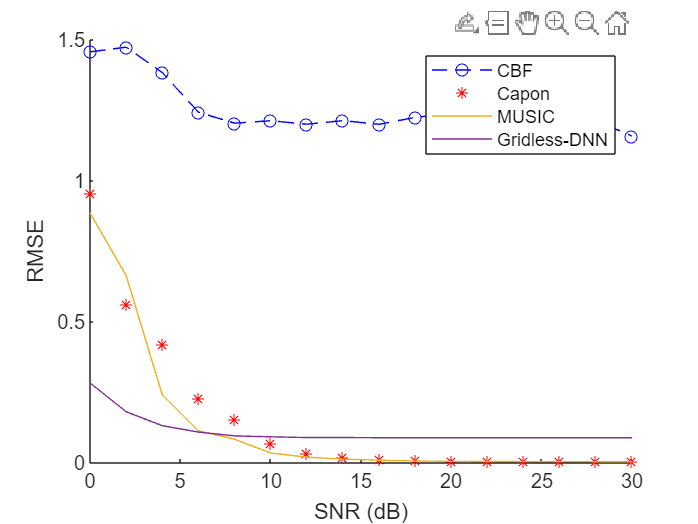

figure; hold on;
plot(SNR_dB_vals, RMSE(1, :), 'b--o');
plot(SNR_dB_vals, RMSE(2, :), 'r*');
plot(SNR_dB_vals, RMSE(3, :));
% plot(SNR_dB_vals, RMSE(4, :));
plot(SNR_dB_vals, RMSE(5, :));
xlabel("SNR (dB)"); ylabel("RMSE");
legend('CBF', 'Capon', 'MUSIC', 'Gridless-DNN');

#### DOA Estimator

function doa_est = DOA_Estimator(spec, angles, doa)
[mags, inds] = findpeaks(spec);
doa_est = zeros(1, 2);
[~, ind] = max(mags);
idx = inds(ind);
doa_est(1) = angles(idx);
mags = [mags(1:ind-1) mags(ind+1:end)];
inds = [inds(1:ind-1) inds(ind+1:end)];
[~, ind] = max(mags);
idx = inds(ind);
doa_est(2) = angles(idx);

[~, ind] = min(abs(doa - doa_est(1)));
if ind == 2
    doa = doa(2:-1:1);
end

if rmse(doa, [doa_est(1) doa_est(1)]) < rmse(doa, doa_est)
    doa_est = [doa_est(1) doa_est(1)];
end
end

#### CBF

function spec = CBF(angles, sensor_locations, y)
spec = zeros(1, length(angles));
for i = 1:length(angles)
    h = exp(1i * pi * sensor_locations.' * cosd(angles(i)));
    spec(i) = abs(h' * (y * y') * h);
end
spec = 10 * log10(spec);
end

#### Capon

function spec = Capon(angles, sensor_locations, y, Ry)
spec = zeros(1, length(angles));
for i = 1:length(angles)
    a = exp(1i * pi * sensor_locations.' * cosd(angles(i)));
    h = (Ry \ a) / (a' / Ry * a);
    spec(i) = abs(h' * (y * y') * h);
end
end

#### MUSIC

function spec = MUSIC(angles, sensor_locations, Ry, M, n)
[eig_vecs, ~] = eig(Ry);
U_N = eig_vecs(:, 1:M-n);
spec = zeros(1, length(angles));
for i = 1:length(angles)
    a = exp(1i * pi * sensor_locations.' * cosd(angles(i)));
    spec(i) = 1 / abs(a' * (U_N * U_N') * a);
end
end

#### DML

function spec = DML(angles, sensor_locations, Ry, M)
spec = zeros(1, length(angles));
for i = 1:length(angles)
    a = exp(1i * pi * sensor_locations.' * cosd(angles(i)));
    PI_a = a * (1 / (a' * a) * a');
    PI_a_ort = eye(M) - PI_a;

    spec(i) = trace(PI_a_ort * Ry);
end
end

#### Gridless DL Model

function r = R2r(R)
M = size(R, 1);
r = zeros(M*M, 1);

re_R = real(R);
im_R = imag(R);

r(1:M) = diag(re_R);
ind = M + 1;
for i = 2:M
    for j = 1:i-1
        r(ind:ind+1) = [re_R(i, j); im_R(i, j)];
        ind = ind + 2;
    end
end
end

function estimated_doa = Gridless_DNN(DOA, net, doa, sensor_locations, R, phi_values)
K = 2;
phi_min = phi_values(1);
delta_phi = phi_values(2);
N = sensor_locations(end) + 1;

z = R(:);
z1 = DOA.Rearrange_According_to_Sensor_Locations(z, sensor_locations);
R_z1 = zeros(N);
for i = 1:N
    z1_i = z1(i:i + N - 1);
    R_z1 = R_z1 + (1 / N) * (z1_i * z1_i');
end

r_z1 = R2r(R_z1);

z = predict(net, r_z1.');

phi_a = zeros(K, 1);
for i = 1:K
    c = floor((doa(i) - phi_min) / delta_phi);
    phi_a(i) = phi_min + c * delta_phi;
end
estimated_doa = zeros(1, K);
if phi_a(2) - phi_a(1) == delta_phi
    c = floor((doa(1) - phi_min) / delta_phi);

    d = sum(z(c+1:c+3)) / 2;

    for i = 1:K % 1:2
        phi_a = phi_min + (c + i - 1) * delta_phi;
        phi_b = phi_a + delta_phi;

        if i == 1
            a = z(c + 1);
            b = d - a;
        else % if i == 2
            b = z(c + 3);
            a = d - b;
        end

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
else
    for i = 1:K
        c = floor((doa(i) - phi_min) / delta_phi);

        phi_a = phi_min + c * delta_phi;
        phi_b = phi_a + delta_phi;

        a = z(c + 1);
        b = z(c + 2);

        estimated_doa(i) = (phi_a * a + phi_b * b) / (a + b);
    end
end
end

function phi_star = Calculate_Phi(inp)
% inp: [phi_a phi_b a b]
K = size(inp, 1);
phi_star = zeros(K, 1);
for i = 1:K
    phi_a = inp(i, 1);
    phi_b = inp(i, 2);
    a = inp(i, 3);
    b = inp(i, 4);

    phi_star(i) = (phi_a * a + phi_b * b) / (a + b);
end
end